# Lab 5

#### Section 1 Transfer Function in Symbolic Form

% Enter symbolic transfer function
syms s k z p1 p2
Av = k*(s+z)/((s+p1)*(s+p2))

$$Av = \frac{k\,\left(s+z\right)}{\left(p_{1}+s\right)\,\left(p_{2}+s\right)}$$

k=25; z=7; p1=0.01; p2=200;
Av=subs(Av)

$$Av = \frac{25\,\left(s+7\right)}{\left(s+\frac{1}{100}\right)\,\left(s+200\right)}$$

#### Section 2 Transfer Function convereted to Continous Time Model

% Convert symbolic equation to numerator and denominator row vectors
[symNum,symDen] = numden(Av)

$$symNum = 2500\,s+17500$$

$$symDen = \left(100\,s+1\right)\,\left(s+200\right)$$

num = sym2poly(symNum)

num =         2500       17500


den = sym2poly(symDen)

den =          100       20001         200



AvTF = tf(num,den)

AvTF =
 
      2500 s + 17500
  -----------------------
  100 s^2 + 20001 s + 200
 
Continuous-time transfer function.
Model Properties


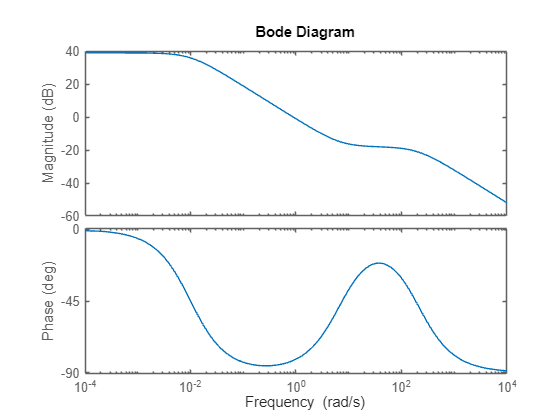

bode(AvTF)

#### Section 3 Setting Bode options

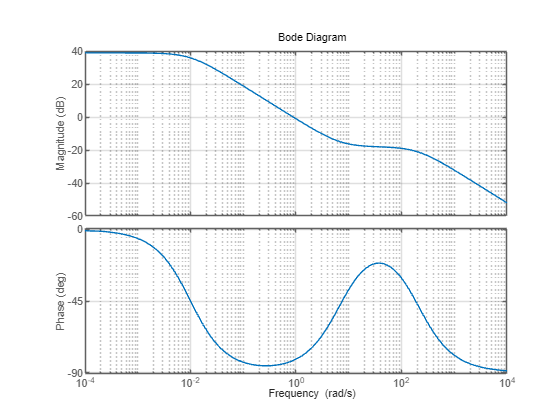

opts = bodeoptions;
%Turning on a grid
opts.Grid = 'on';
bode(AvTF,opts)

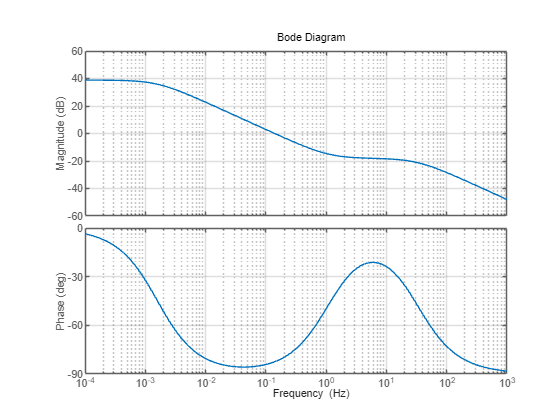


%Setting x and y limits
opts = bodeoptions;
opts.Grid = 'on';
opts.xlim = [10^-4 10^3];
opts.ylim = {[-60 60],[-90 0]};
opts.FreqUnits = 'Hz';
bode(AvTF,opts)


Av2 = 8*(s+0.05)/(s+3)

$$Av2 = \frac{8\,s+\frac{2}{5}}{s+3}$$

[symNum,symDen] = numden(Av2)

$$symNum = 40\,s+2$$

$$symDen = 5\,s+15$$

num = sym2poly(symNum)

num =     40     2


den = sym2poly(symDen)

den =      5    15



Av2TF = tf(num,den)

Av2TF =
 
  40 s + 2
  --------
  5 s + 15
 
Continuous-time transfer function.
Model Properties


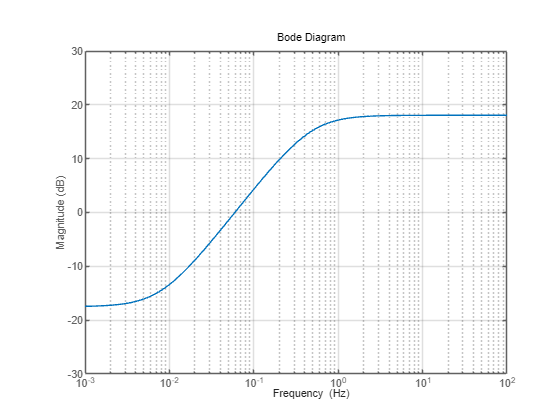


% Only magnitude plot
opts = bodeoptions;
opts.Grid = 'on';
opts.PhaseVisible = 'off';
opts.xlim = [10^-3 10^2];
opts.ylim = {[-30 30],[-90 0]};
opts.FreqUnits = 'Hz';
bode(Av2TF,opts)

#### Section 4 Transfer Function

syms s C1 R1 R2
% Symbolic Function
Zc = 1/(s*C1);
Zp = simplifyFraction(R2*Zc/(R2+Zc));
Zin = simplifyFraction(R1 + Zp);
Av3 = simplifyFraction(Zp/Zin);
% Plug in values
C1=2; R1=5; R2=3;
Av3=subs(Av3);

$$Av3 = \frac{3}{30\,s+8}$$

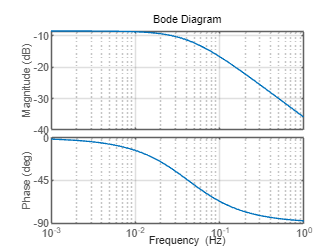

%Convert to polynomials
[symNum, symDen] = numden(Av3);
num = sym2poly(symNum);
den = sym2poly(symDen);
% Create a continuous-time model of the transfer function
Av3TF = tf(num,den);
%bode(Av3TF)

s=tf('s');
C1=2; R1=5; R2=3;
ZC1=1/(s*C1);
Zp = minreal(R2*ZC1/(R2+ZC1));
Zin = minreal(R1 + Zp);
Av4 = minreal(Zp/Zin);

opts = bodeoptions;
opts.Grid = 'on';
opts.FreqUnits = 'Hz';
bode(Av4,opts)

#### Section 5 RC Circuit

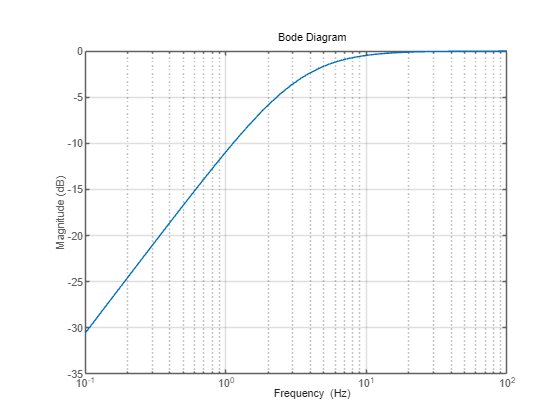

syms s C R
Zc=1/(s*C);
Av5 = simplifyFraction(R/(R+Zc));
C=0.0047;R=10;
Av5=subs(Av5);
[symNum, symDen] = numden(Av5);
num = sym2poly(symNum);
den = sym2poly(symDen);
Av5TF = tf(num,den);
opts = bodeoptions;
opts.Grid = 'on';
opts.PhaseVisible = 'off';
opts.FreqUnits = 'Hz';
bode(Av5TF,opts)